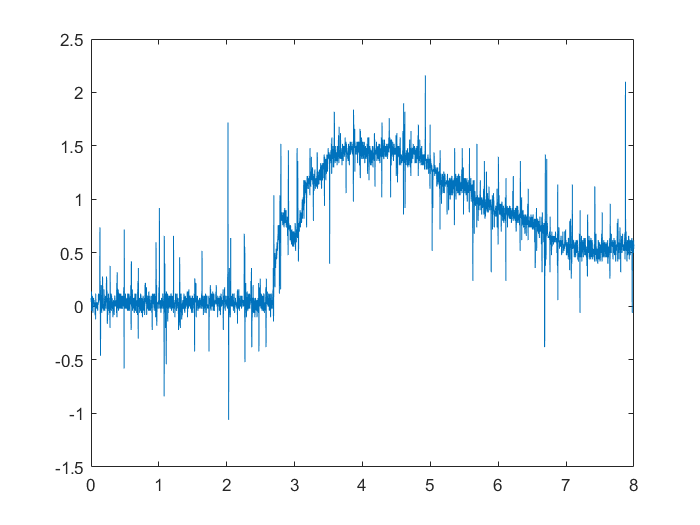

Ts=2e-3;
fs=1/Ts;
Vs=5e-1;
t(1)=0;
for i=2:length(Source)
    t(i)=t(i-1)+Ts;
end
data=Source*Vs/25 -1;
plot(t,data)

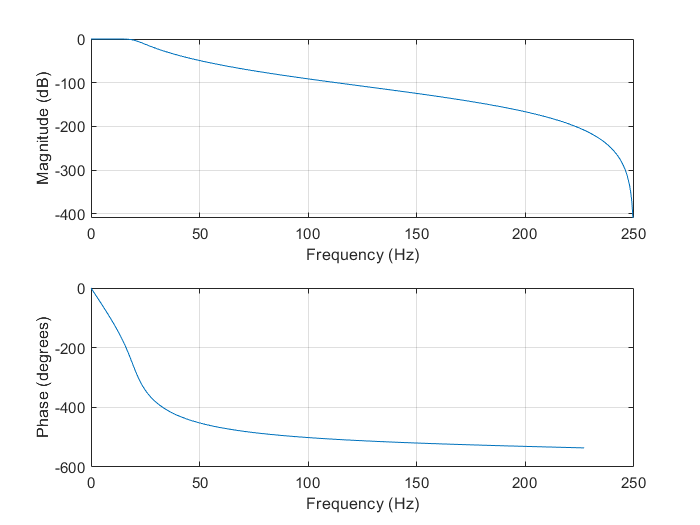

fc=20;
[num,den]=butter(6,fc/(fs/2));
freqz(num,den,[],fs)

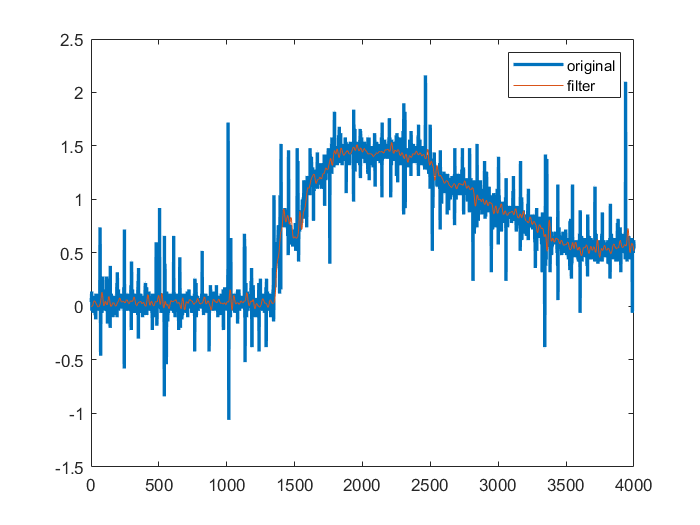


DataOut=filter(num,den,data);

plot(data,'LineWidth',2)
hold on

plot(DataOut)
hold off
legend('original','filter')

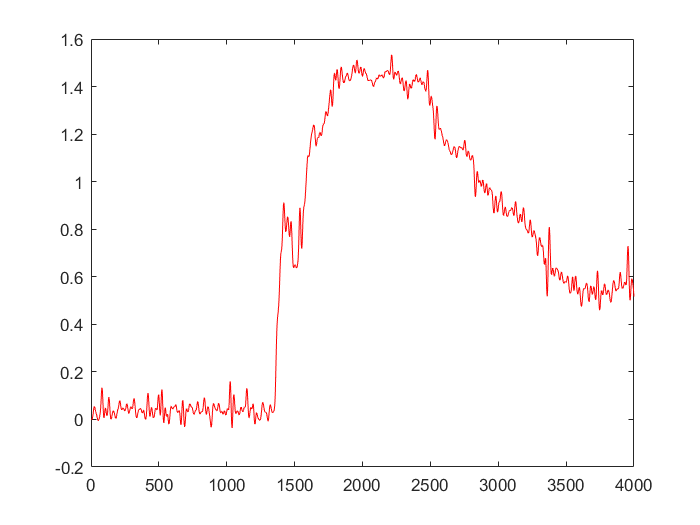


plot(DataOut,'r')

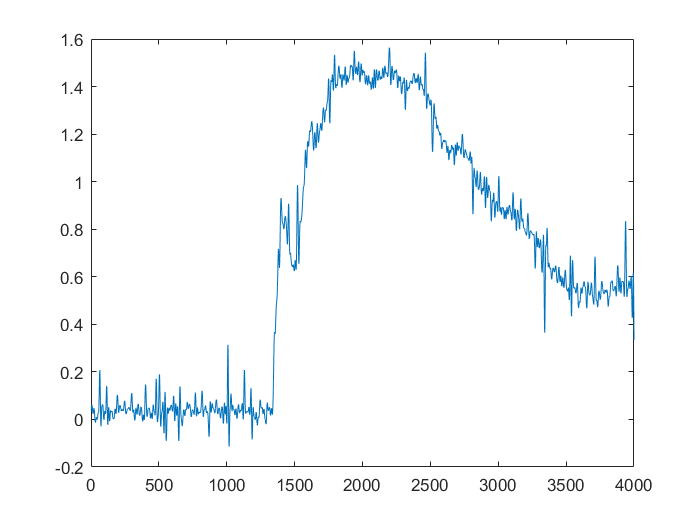

data2Out=lowpass(data,20,fs);
plot(data2Out)